% --- Setup ---
clear
sympref('AbbreviateOutput', false);

% === Uniform Load - Stresses and Displacements ====
syms l h w nu x y w0 I E G real

psi = w0*( -10*h^3*x^2 ...
           + y^3*(2*h^2 + 5*(l - x)^2) ...
           - 15*h^2*x*y*(x - 2*l) ...
           - y^5 ) ...
      /(40*h^3);
psi = subs(psi,[y,w0],[-y,-w0]);

a =  w0/h^3;
b =  w0*l/h^3;
c = -w0/(2*h) - w0*l^2/(6*h^3) - w0*nu*l/(4*h);
d = -w0*nu/4;
e =  3*w0/(4*h);
f = -3*w0*l/(4*h);
g = -w0/4;

% Airy stress function
psi = simplify(a*( (1/5)*y^5 - x^2*y^3 ) ...
    + b*x*y^3 ...
    + c*y^3 ...
    + d*y^2 ...
    + e*x^2*y ...
    + f*x*y ...
    + g*x^2)

$$psi = -\frac{w_{0}\,\left(15\,h^{3}\,x^{2}+15\,\nu \,h^{3}\,y^{2}+45\,h^{2}\,l\,x\,y+15\,\nu \,h^{2}\,l\,y^{3}-45\,h^{2}\,x^{2}\,y+30\,h^{2}\,y^{3}+10\,l^{2}\,y^{3}-60\,l\,x\,y^{3}+60\,x^{2}\,y^{3}-12\,y^{5}\right)}{60\,h^{3}}$$



% [~, v_mid_w0,~,~,~] = Airy_Solution(psi)


% === superpose with concentrated load to enforce BC ====
syms P
v_mid_P = P/(6*E*I)*(-x^3+3*l^2*x-2*l^3);
u_mid_P = 0;

% P_star = solve(subs(v_mid_w0+v_mid_P,x,0)==0,P,'ReturnConditions',false);

% v = decompose(collect(expand(subs(v_mid_P,P,P_star) + v_mid_w0),[1/(E*I), 1/(G*I),w0]))

% cantilever
u = 0;  v = w0/(24*E*I)*(l-x)^2*x^2 + w0*h^2*x*(l-x)/(16*G*I)

$$v = \frac{w_{0}\,x^{2}\,{\left(l-x\right)}^{2}}{24\,\text{E}\,\text{I}}+\frac{h^{2}\,w_{0}\,x\,\left(l-x\right)}{16\,G\,\text{I}}$$


% propped cantilever
u = simplify((w0*nu/(2*E))*x - (nu*w0*l)/(2*E))

$$u = -\frac{\nu \,w_{0}\,\left(l-x\right)}{2\,\text{E}}$$


v = decompose(collect(expand((w0*x/(48*E*I))*(2*x^3 - 3*l*x^2 + l^3) ...
     + (w0*h^2/(20*E*I*l)) * (l - x)^2 * x + (w0*h^2/(G*I*l)) * (5*nu)/(320*(1+nu)) * (l - x)^2 * x)))

$$ans = 0$$

$$v = \frac{w_{0}\,x\,{\left(l-x\right)}^{2}\,\left(12\,h^{2}+5\,l^{2}+10\,x\,l\right)}{240\,\text{E}\,\text{I}\,l}+\frac{h^{2}\,\nu \,w_{0}\,x\,{\left(l-x\right)}^{2}}{64\,G\,\text{I}\,l\,\left(\nu +1\right)}$$



v = subs(v,[G, I],[E/(2*(1+nu)), 2/3*h^3])

$$v = \frac{w_{0}\,x\,{\left(l-x\right)}^{2}\,\left(12\,h^{2}+5\,l^{2}+10\,x\,l\right)}{160\,\text{E}\,h^{3}\,l}+\frac{3\,\nu \,w_{0}\,x\,\left(2\,\nu +2\right)\,{\left(l-x\right)}^{2}}{128\,\text{E}\,h\,l\,\left(\nu +1\right)}$$

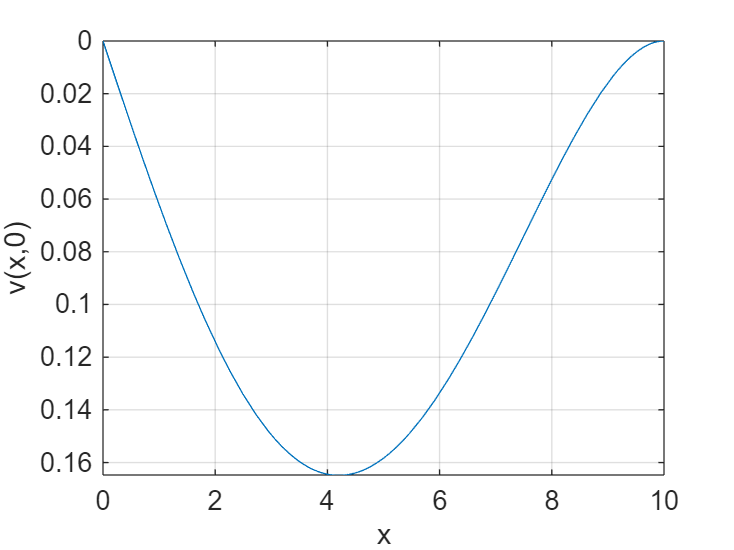

v0 = subs(v,[w0,l,h,nu,E],[1,10,1,0.2,500]);

v_fun = matlabFunction(v0, 'Vars', x);
fplot(v_fun, [0, 10]); grid on
xlabel('x'); ylabel('v(x,0)');
set(gca, 'YDir', 'reverse')

function [u_mid_w0, v_mid_w0, sigma_x, sigma_y, tau_xy] = Airy_Solution(psi)
    syms k l h w E nu x y w0 I G real

    sigma_x = simplify(diff(diff(psi,y),y))
    sigma_y = diff(diff(psi,x),x)
    tau_xy  = -diff(diff(psi,x),y)
    
    syms f1(y) f2(x)
    
    % Hooke's Law
    u = 1/E*int(sigma_x-nu*sigma_y,x) + f1(y);
    v = 1/E*int(sigma_y-nu*sigma_x,y) + f2(x);
    
    % Shear Compatibility
    R = simplify(diff(u,y) + diff(v,x) - tau_xy/G);
    
    % Split R into y-only and x-only parts:
    K = simplify(subs(R,{x,y,f1(y),f2(x)},{0,0,0,0}))
    Gy  = simplify(subs(R-K,{f2(x),diff(f2(x),x)},{0,0}));     % function of y only
    Gy  = simplify(subs(Gy,x,0));
    Gy  = simplify(subs(Gy,diff(f1(y)),0));
    Fx  = simplify(subs(R-K,{f1(y),diff(f1(y),y)},{0,0}));     % function of x only
    Fx  = simplify(subs(Fx,y,0));
    Fx  = simplify(subs(Fx,diff(f2(x)),0));
    
    syms C1 C2 C3 C4 real
    f1_sol = int(-Gy, y) - C1*y + C2;
    f2_sol = int(-Fx, x) - C3*x + C4;
    
    C1_sol = solve(subs(R,[f1(y),f2(x)],[f1_sol,f2_sol])==0,C1);
    
    % substitute back
    u = simplify(subs(u, f1(y), f1_sol));
    u = simplify(subs(u, C1, C1_sol));
    v = simplify(subs(v, f2(x), f2_sol));
    
    % verify
    chk3 = simplify(subs(diff(u,y) + diff(v,x) - tau_xy/G,G,E/(2*(1+nu))))        % -> 0
    
    % apply weak clamp dv/dx(l)=0
    eqs = [ 
        subs(u,{x,y},{l,0})==0, ...
            subs(v,{x,y},{l,0})==0, ...
            subs(diff(v,x),{x,y},{l,0})==0 ];
    
    S = solve(eqs, [C2,C3,C4], 'ReturnConditions', false);
    u = simplify(subs(u, [C2,C3,C4], [S.C2 S.C3 S.C4]));
    v = simplify(subs(v, [C2,C3,C4], [S.C2 S.C3 S.C4]));
    
    % Midline expressions
    u_mid_w0 = simplify(subs(u, [y, h^3], [0, 3/2*I]));
    v_mid_w0 = collect(expand(subs(v, [y, h^3], [0, 3/2*I])),[1/(E*I), 1/(G*I), w0]);
    
    v_mid_w0 = decompose(v_mid_w0)
end


% decompose elastic line to shear and bending terms
function v_mid_grouped = decompose(v_mid)
    syms pE pG E G I
    % already have v_mid in terms of I; if not, do h^3->(3/2)*I before this line
    vpg = simplify(subs(v_mid, [1/(E*I), 1/(G*I)], [pE, pG]));
    vpg = collect(vpg, [pE, pG]);
    
    [coef, mon] = coeffs(vpg, [pE, pG]);
    
    A0_pg = sym(0);  AE_pg = sym(0);  AG_pg = sym(0);  ABOTH_pg = sym(0);
    for k = 1:numel(mon)
        ie = feval(symengine,'degree', mon(k), pE);
        ig = feval(symengine,'degree', mon(k), pG);
        term = coef(k)*mon(k);
        if     ie==0 && ig==0, A0_pg = A0_pg + term;         % no E*I/GI
        elseif ie==1 && ig==0, AE_pg = AE_pg + term;         % 1/(E*I)
        elseif ie==0 && ig==1, AG_pg = AG_pg + term;         % 1/(GI)
        else,                  ABOTH_pg = ABOTH_pg + term;   % mixed/higher (should be 0)
        end
    end
    
    % numerators for the two single fractions
    AE = simplify(subs(AE_pg, pE, 1));   % numerator of 1/(E*I)
    AG = simplify(subs(AG_pg, pG, 1));   % numerator of 1/(G*I)
    A0 = simplify(A0_pg);                 % E*I/GI–free part (usually 0)
    
    v_mid_grouped = A0 + AE/(E*I) + AG/(G*I);
    
    % (optional) sanity check: expect no mixed/higher-power leftovers
    simplify(subs(ABOTH_pg, [pE,pG], [1/(E*I), 1/(G*I)]))    % -> 0
end


function psi = assemble_Airy()
    syms k l h w E nu x y alpha w0 I G real
    assume([k l h w E nu alpha w0],'real');
    assumeAlso([l h E] > 0);
    assumeAlso(-1 < nu & nu < 1/2);
    
    % === Distributed Exp. Load - Stresses ====
    % Airy stress function
    syms A B C D real
    f   = (A + B*y)*cos(alpha*y) + (C + D*y)*sin(alpha*y);
    phi = f*exp(alpha*x);
    
    % Stresses from Airy
    sigma_x = simplify(diff(phi, y, 2));
    sigma_y = simplify(diff(phi, x, 2));      % = alpha^2*exp(alpha*x)*f(y)
    tau_xy  = simplify(-diff(diff(phi, x), y)); % = -alpha*exp(alpha*x)*f'(y)
    
    % Boundary conditions 
    eqs = [
      subs(f, y, -h) == w/alpha^2, ...
      subs(f, y,  h) == 0, ...
      subs(diff(f,y), y,  h) == 0, ...
      subs(diff(f,y), y, -h) == 0];
    
    S = solve(eqs, [A, B, C, D], 'ReturnConditions', false);
    
    A_sol = simplify(S.A);
    B_sol = simplify(S.B);
    C_sol = simplify(S.C);
    D_sol = simplify(S.D);
    
    % Substitute back
    phi     = simplify(subs(phi,     [A B C D], [A_sol B_sol C_sol D_sol]));
    sigma_x = subs(sigma_x, [A B C D], [A_sol B_sol C_sol D_sol]);
    sigma_y = simplify(subs(sigma_y, [A B C D], [A_sol B_sol C_sol D_sol]));
    tau_xy  = subs(tau_xy,  [A B C D], [A_sol B_sol C_sol D_sol]);
    
    % --- Quick verification of BCs (all should reduce to 0) ---
    bc1 = simplify(subs(sigma_y, y, -h) - w*exp(alpha*x));
    bc2 = simplify(subs(sigma_y, y,  h));
    bc3 = simplify(subs(tau_xy,  y,  h));
    bc4 = simplify(subs(tau_xy,  y, -h));
end
